#### Functions

rotx = @(radians) [1,0,0;
                   0,cos(radians),-sin(radians);
                   0,sin(radians),cos(radians)];
               
roty = @(radians) [cos(radians),0,sin(radians);
                   0,1,0;
                   -sin(radians),0,cos(radians)];
               
rotz = @(radians) [cos(radians), -sin(radians), 0;
                   sin(radians), cos(radians),0;
                   0,0,1];
               
d2r = @(degree) degree*pi/180;

syms g11 g12 g13 g21 g22 g23 g31 g32 g33 real;
syms A C real;
syms Lx Ly Lz Px Py Pz real;
G = [g11,g12,g13;
     g21,g22,g23;
     g31,g32,g33];
 
invG = inv(G);

A_Q_P = [cos(C),-cos(A)*sin(C),sin(A)*sin(C),Lx;
         sin(C),cos(A)*cos(C),-cos(C)*sin(A),Ly;
         0,sin(A),cos(A),Lz;
         0,0,0,1];

#### Input

prev_R = eye(3,3);
prev_pose = [0,0,0,prev_R(1,3),prev_R(2,3),prev_R(3,3)];
offset = prev_pose(1:3);
pose_R_actual = roty(d2r(-45));
pose = [0,0,0,pose_R_actual(1,3),pose_R_actual(2,3),pose_R_actual(3,3)];
% first 3 terms of prev pose is offset.
% last 3 terms of prev pose is useless as the full rotation matrix of the
% prev pose should be stored.

#### Inverse Kinematics

out = zeros([1,5]);

invG = subs(invG,'g11',prev_R(1,1));
invG = subs(invG,'g12',prev_R(1,2));
invG = subs(invG,'g13',prev_R(1,3));
invG = subs(invG,'g21',prev_R(2,1));
invG = subs(invG,'g22',prev_R(2,2));
invG = subs(invG,'g23',prev_R(2,3));
invG = subs(invG,'g31',prev_R(3,1));
invG = subs(invG,'g32',prev_R(3,2));
invG = subs(invG,'g33',prev_R(3,3));
    
relative_rot = invG*pose_R_actual;

out(4) = asin(relative_rot(3,2));
out(5) = atan(relative_rot(2,1)/relative_rot(1,1));
out(1) = cos(out(5))*(pose(1)-offset(1)) + sin(out(5))*(pose(2)-offset(2));
out(2) = -sin(out(5))*cos(out(4))*(pose(1)-offset(1)) +...
        cos(out(5))*cos(out(4))*(pose(2)-offset(2)) + ...
        sin(out(4))*(pose(3)-offset(3));
out(3) = sin(out(5))*sin(out(4))*(pose(1)-offset(1)) -...
        cos(out(5))*sin(out(4))*(pose(2)-offset(2)) + ...
        cos(out(4))*(pose(3)-offset(3));
    

#### Plot 

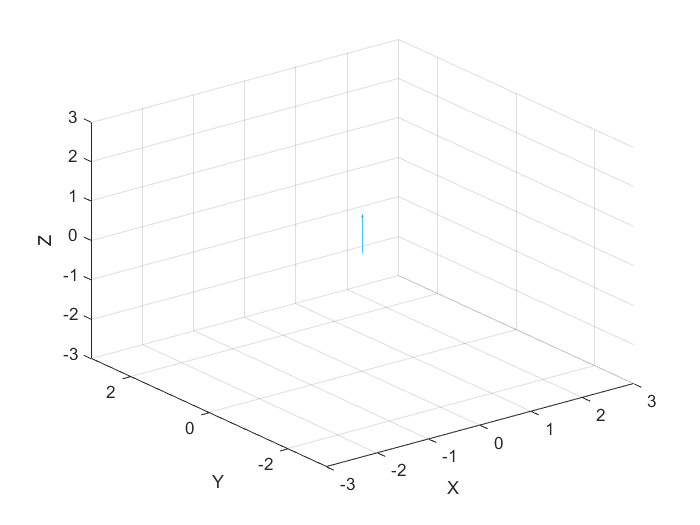

axis_vec = [-3,3,-3,3,-3,3];
[O,Q]=forKinPlot(out,offset,pose,prev_pose,prev_R,axis_vec,1,5);